clc 
clear all

First of all lets import the matrix map

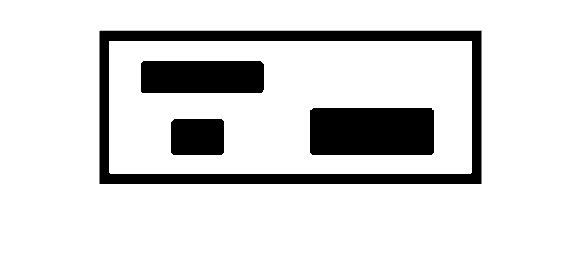

load image_map.mat
imshow(image_map)

the map is composed of 0 and 1, to compute the path from two points it can be useful to use another number to descriminate the path from the obsrtacles and the free space. I have chosen to use the number 2, so lets add the initial and fibal points to the map

qi=[30 125] 

qi =     30   125


qf=[135 400]

qf =    135   400


image_map=double(image_map);
image_map_col=image_map;
image_map(qi(1),qi(2))=2;
image_map(qf(1),qf(2))=2;
imshow(image_map)

Lets define the RRT algoritm

qlist=[qi];
delta=20; %%INTESO COME NUMERO DI PASSI NON COME DISTANZA
n_exec=200;
for j=1:n_exec
    qrand=[randi(size(image_map,1)),randi(size(image_map,2))];
    qnear=qlist(knnsearch(qlist,qrand),:);
    qnext=qnear;
    for i=1:delta
        direction= atan2(qrand(2)-qnext(2),qrand(1)-qnext(1));
        direction_degree = rad2deg(direction);
        switch true
            case direction_degree>-22.5 && direction_degree<=22.5
                if image_map_col(qnext(1)+1,qnext(2)+0) == 1
                    qnext=qnext+[1,0];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>22.5 && direction_degree<=67.5
                if image_map_col(qnext(1)+1,qnext(2)+1) == 1
                    qnext=qnext+[1,1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>67.5 && direction_degree<=112.5
                if image_map_col(qnext(1)+0,qnext(2)+1) == 1
                    qnext=qnext+[0,1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>112.5 && direction_degree<=157.5
                if image_map_col(qnext(1)-1,qnext(2)+1) == 1
                    qnext=qnext+[-1,1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>157.5 && direction_degree<=180
                if image_map_col(qnext(1)-1,qnext(2)+0) == 1
                    qnext=qnext+[-1,0];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>=-180 && direction_degree<-157.5
                if image_map_col(qnext(1)-1,qnext(2)+0) == 1
                    qnext=qnext+[-1,0];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>=-157.5 && direction_degree<-112.5
                if image_map_col(qnext(1)-1,qnext(2)-1) == 1
                    qnext=qnext+[-1,-1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end            
            case direction_degree>=-112.5 && direction_degree<-67.5
                if image_map_col(qnext(1)+0,qnext(2)-1) == 1
                    qnext=qnext+[0,-1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>=-67.5 && direction_degree<=-22.5
                if image_map_col(qnext(1)-1,qnext(2)+1) == 1
                    qnext=qnext+[-1,+1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end    
            end
    end
    
    if (qnext(2) ~= qnear(2))  || (qnext(1) ~= qnear(1))
        qlist=[qlist;qnext];
    end
end
    qnearest=qlist(knnsearch(qlist,qf),:);
    if(norm((qnearest-qf),1)<=delta)
        qnext=qnearest;
        for i=1:delta
        direction= atan2(qf(2)-qnext(2),qf(1)-qnext(1));
        direction_degree = rad2deg(direction);
        switch true
            case direction_degree>-22.5 && direction_degree<=22.5
                if image_map_col(qnext(1)+1,qnext(2)+0) == 1
                    qnext=qnext+[1,0];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>22.5 && direction_degree<=67.5
                if image_map_col(qnext(1)+1,qnext(2)+1) == 1
                    qnext=qnext+[1,1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>67.5 && direction_degree<=112.5
                if image_map_col(qnext(1)+0,qnext(2)+1) == 1
                    qnext=qnext+[0,1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>112.5 && direction_degree<=157.5
                if image_map_col(qnext(1)-1,qnext(2)+1) == 1
                    qnext=qnext+[-1,1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>157.5 && direction_degree<=180
                if image_map_col(qnext(1)-1,qnext(2)+0) == 1
                    qnext=qnext+[-1,0];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>=-180 && direction_degree<-157.5
                if image_map_col(qnext(1)-1,qnext(2)+0) == 1
                    qnext=qnext+[-1,0];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>=-157.5 && direction_degree<-112.5
                if image_map_col(qnext(1)-1,qnext(2)-1) == 1
                    qnext=qnext+[-1,-1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end            
            case direction_degree>=-112.5 && direction_degree<-67.5
                if image_map_col(qnext(1)+0,qnext(2)-1) == 1
                    qnext=qnext+[0,-1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end
            case direction_degree>=-67.5 && direction_degree<=-22.5
                if image_map_col(qnext(1)-1,qnext(2)+1) == 1
                    qnext=qnext+[-1,+1];
                    image_map(qnext(1),qnext(2))=2;
                else
                    i=delta+1;
                end    
            end
            if(qnext==qf)
                i=delta+1;
            end
        end
    end
    

lets show the resulting map

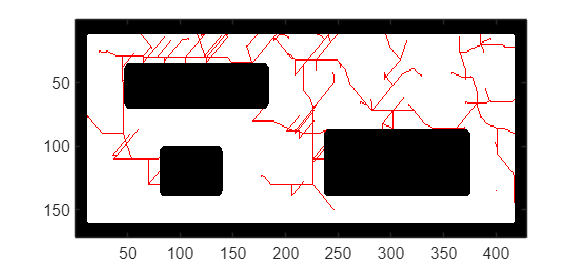

map_colori = [0, 0, 0;  % white for 0
              1, 1, 1;  % black for 1
              1, 0, 0]; % red for 2
imagesc(image_map)
colormap(map_colori)

secondo metodo

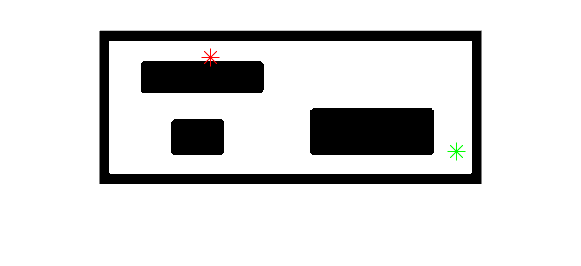

% show the map
imshow(image_map);
hold on
scatter(qi(2),qi(1),100,'r','*');
scatter(qf(2),qf(1),100,'g','*');

nearestNodeIdx = 1

nearestNodeIdx = 1

nearestNodeIdx = 2

nearestNodeIdx = 3

nearestNodeIdx = 4

nearestNodeIdx = 1

nearestNodeIdx = 1

nearestNodeIdx = 1

nearestNodeIdx = 5

nearestNodeIdx = 5

nearestNodeIdx = 1

nearestNodeIdx = 6

nearestNodeIdx = 5

nearestNodeIdx = 7

nearestNodeIdx = 7

nearestNodeIdx = 1

nearestNodeIdx = 7

nearestNodeIdx = 3

nearestNodeIdx = 9

nearestNodeIdx = 3

nearestNodeIdx = 9

nearestNodeIdx = 9

nearestNodeIdx = 1

nearestNodeIdx = 2

nearestNodeIdx = 1

nearestNodeIdx = 1

nearestNodeIdx = 9

nearestNodeIdx = 4

nearestNodeIdx = 12

nearestNodeIdx = 11

nearestNodeIdx = 14

nearestNodeIdx = 2

nearestNodeIdx = 6

nearestNodeIdx = 15

nearestNodeIdx = 1

nearestNodeIdx = 14

nearestNodeIdx = 13

nearestNodeIdx = 1

nearestNodeIdx = 11

nearestNodeIdx = 2

nearestNodeIdx = 17

nearestNodeIdx = 15

nearestNodeIdx = 1

nearestNodeIdx = 9

nearestNodeIdx = 1

nearestNodeIdx = 18

nearestNodeIdx = 20

nearestNodeIdx = 18

nearestNodeIdx = 19

nearestNodeIdx = 22

nearestNodeIdx = 8

nearestNodeIdx = 13

nearestNodeIdx = 19

nearestNodeIdx = 17

nearestNodeIdx = 2

nearestNodeIdx = 8

nearestNodeIdx = 23

nearestNodeIdx = 17

nearestNodeIdx = 23

nearestNodeIdx = 19

nearestNodeIdx = 23

nearestNodeIdx = 16

nearestNodeIdx = 17

nearestNodeIdx = 26

nearestNodeIdx = 1

nearestNodeIdx = 17

nearestNodeIdx = 27

nearestNodeIdx = 21

nearestNodeIdx = 28

nearestNodeIdx = 6

nearestNodeIdx = 27

nearestNodeIdx = 28

nearestNodeIdx = 23

nearestNodeIdx = 28

nearestNodeIdx = 18

nearestNodeIdx = 17

nearestNodeIdx = 9

nearestNodeIdx = 24

nearestNodeIdx = 21

nearestNodeIdx = 20

nearestNodeIdx = 27

nearestNodeIdx = 10

nearestNodeIdx = 10

nearestNodeIdx = 29

nearestNodeIdx = 12

nearestNodeIdx = 17

nearestNodeIdx = 25

nearestNodeIdx = 21

nearestNodeIdx = 31

nearestNodeIdx = 17

nearestNodeIdx = 17

nearestNodeIdx = 11

nearestNodeIdx = 21

nearestNodeIdx = 28

nearestNodeIdx = 28

nearestNodeIdx = 32

nearestNodeIdx = 14

nearestNodeIdx = 6

nearestNodeIdx = 27

nearestNodeIdx = 25

nearestNodeIdx = 5

nearestNodeIdx = 27

nearestNodeIdx = 34

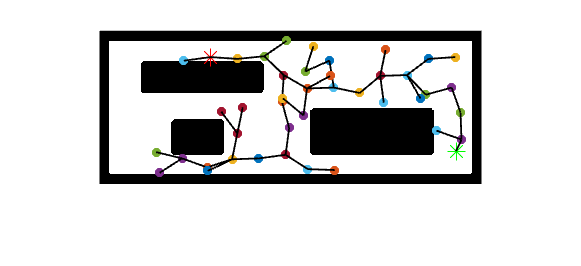


n_rows=size(image_map, 1);
n_columns=size(image_map, 2);

max_iteration = 300;
delta=30;
goalReached = false;
qlist = [qi]; 


% Creation of the tree
for iter = 1:max_iteration
    q_rand = [randi([1, n_rows]); randi([1, n_columns])]; 
    distances = sqrt(sum((qlist(:, 1:2) - q_rand').^2, 2));
    [~, nearestNodeIdx] = min(distances);
    q_near = qlist(nearestNodeIdx, 1:2);
   
    x_new =round( q_near(2) + delta * cos(atan2(q_rand(1) - q_near(1), q_rand(2) - q_near(2))));
    y_new =round( q_near(1) + delta * sin(atan2(q_rand(1) - q_near(1), q_rand(2) - q_near(2))));
    q_new = [y_new; x_new];

    % connection between q_near and q_new
    line = round([linspace(q_near(1), q_new(1), 100); linspace(q_near(2), q_new(2), 100)]);
 
    collision = false; 
    for i = 1:size(line, 2)
        if image_map(line(1, i), line(2, i)) == 0
            collision = true;
            break; 
        end
    end

    if ~collision
        qlist = [qlist; q_new']; 
        plot(q_new(2), q_new(1), '*', 'MarkerSize', 5, 'LineWidth', 2); 
        plot([q_near(2), x_new], [q_near(1), y_new], 'k', 'LineWidth', 1); 
    
    end

    %goal reaching  
    distance_to_goal = sqrt((qf(1) - q_near(1))^2 + (qf(2) - q_near(2))^2);
    if distance_to_goal <= delta
        qlist = [qlist; qf]; 
        plot([q_near(2), qf(2)], [q_near(1), qf(1)], 'k', 'LineWidth', 1); 
        goalReached=true;
        break; 
        
    else
         goalReached=false;
    end

end


if goalReached
disp('Goal Reached!');
else
disp('Goal not reached within maximum iterations.');
end

Goal Reached!
